

load("intercluster_strength_data_A09threshold.mat")

%use git code multicat: https://github.com/GenLouvain/GenLouvain/blob/master/HelperFunctions/multiaspect.m
%multilayer modularity (categorical coupling)

gamma = 1;
omega = 0.5;

N=64;
T=20;
[B,twom] = multicat(Al, gamma, omega);
[S,Q]= genlouvain(B);

Merging 1280 communities  02-Apr-2023 16:34:00
64 change: 6080 total: 6080 relative: 1
64 change: 0 total: 6080 relative: 0
Merging 64 communities  02-Apr-2023 16:34:00
17 change: 224.9779 total: 6304.9779 relative: 0.035683
10 change: 40.256 total: 6345.2339 relative: 0.0063443
10 change: 4.4585 total: 6349.6924 relative: 0.00070217
9 change: 10.1532 total: 6359.8457 relative: 0.0015965
9 change: 0.55131 total: 6360.397 relative: 8.6679e-05
9 change: 0.56251 total: 6360.9595 relative: 8.8431e-05
9 change: 0 total: 6360.9595 relative: 0
Merging 9 communities  02-Apr-2023 16:34:00
4 change: 34.4694 total: 6395.4289 relative: 0.0053897
4 change: 0 total: 6395.4289 relative: 0
Merging 4 communities  02-Apr-2023 16:34:00
3 change: 2.7877 total: 6398.2166 relative: 0.00043569
3 change: 0 total: 6398.2166 relative: 0
Merging 3 communities  02-Apr-2023 16:34:00
3 change: 0 total: 6398.2166 relative: 0


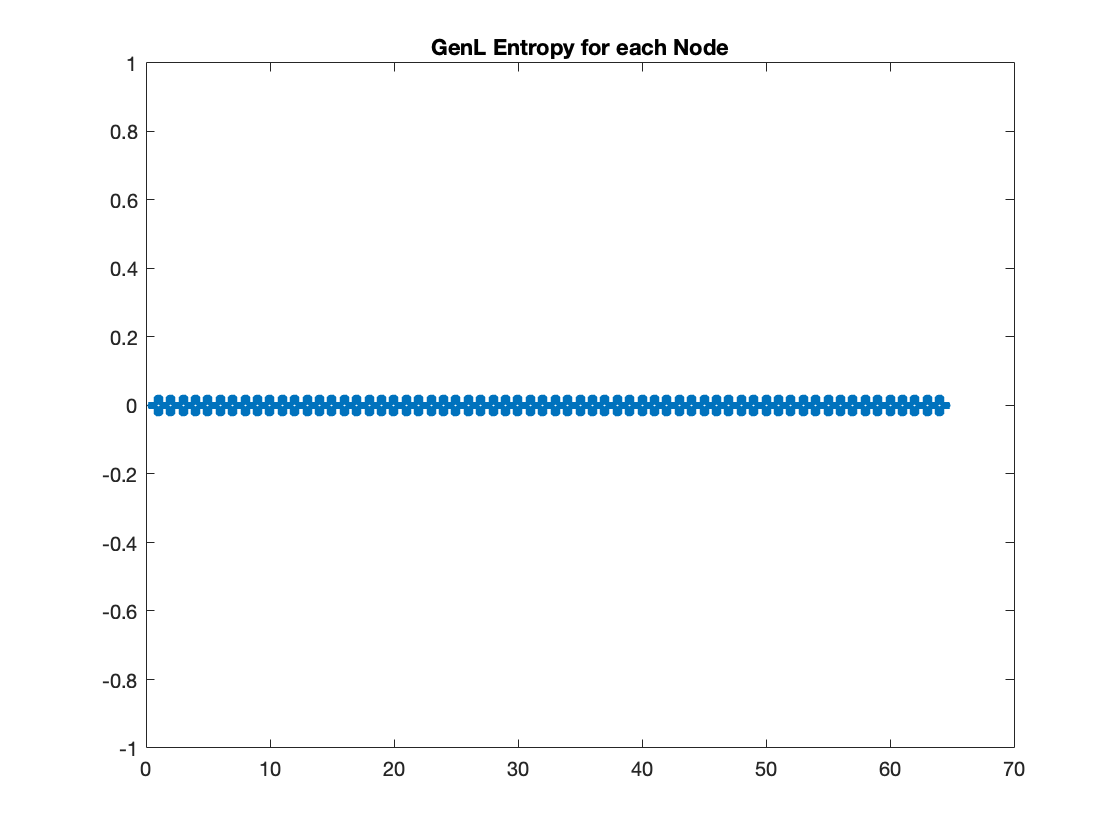

Q=Q/twom;
S=reshape(S,N,T);

un_len = max(S(:));

S= S';

layer_nodes_per_cluster = [];
for i=1:un_len
    binary_matrix = (S==i);
    layer_nodes_per_cluster = [layer_nodes_per_cluster, {(binary_matrix)}];
end


%g -> each entry will tell you how many times out of 20 subjects node i was assigned to community
g = [];
prob = []; %probability distribution

for i=1:64
    g = [g, {zeros(un_len,1)}];
    prob = [prob, {zeros(un_len,1)}];
end


%entropy
%lower entropy , high variability
%high entropy, not much variation


H = zeros(64,1);

%g = [1,2,3,4,5,6,7,8,9...64]
%g[1] = [1...23] , across all clusters


for cluster=1:un_len
    for layer=1:L
        for node=1:N
            node_temp = layer_nodes_per_cluster{1,cluster}(layer,node);
            g{node}(cluster,1) = g{node}(cluster,1) + node_temp;
        end
    end
end

%p_{i} = g_{i}/sum_{k}g_{i}(k),p_{i} is a vector K x 1 
% sum((all k that contain i)_g(len(23))

for node=1:N
    sum_of_node_in_Ks = sum(g{node});
    for cluster=1:un_len
        prob{node}(cluster,1)= g{node}(cluster,1)/sum_of_node_in_Ks;
    end
end


for node=1:N
    sum_of_prob_in_Ks = 0;
    for cluster=1:un_len
        if prob{node}(cluster,1) ~= 0
            temp = prob{node}(cluster,1)*log2(prob{node}(cluster,1));
            sum_of_prob_in_Ks = sum_of_prob_in_Ks + temp;
        end
    end
    H(node) = -1*sum_of_prob_in_Ks;
end

figure;
plot(H,'o','LineWidth',5)
hold on;
title(sprintf('GenL Entropy for each Node'));     
hold off;